%лр9
%задание 1
x=(0:0.2:10)

x =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000


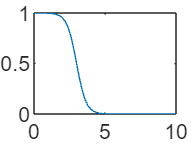

y=sigmf(x,[-3 3]);
plot(x,y)

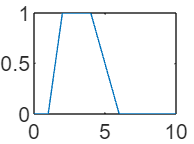

%задание 2
% построение нечёткой импликации I(A,B)=min(A,B)

y1 = trapmf(x, [1 2 4 6]);
plot(x,y1);


y2 = trapmf(x, [1 2 4 6]);
plot(x2,y2);

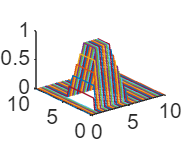


[X, Y] = meshgrid(x,x);
Z = min(trapmf(X, [1 2 4 6]),trapmf(Y, [1 2 4 6]));
plot3(X,Y,Z);

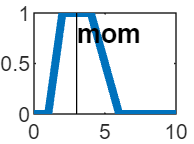


%задание3
% дефаззификация - метод среднего максимума (mom)
% построение импликации
x = (0:0.2:10);
mf1 = trapmf(x, [1 2 4 6]);
mf2 = trapmf(x, [1 2 4 6]);
mf = min(trapmf(x, [1 2 4 6]),trapmf(x, [1 2 4 6]));
figure('Tag', 'defuzz');
%построение графика функции принадлежности mf с толщиной линии 3
plot(x,mf, 'LineWidth',3);
%Получается текущая ось графика.
h_gca = gca;
%деления по оси Y в точках 0, 0.5 и 1.
h_gca.YTick = [0 0.5 1];
ylim([0 1]);
%дефаззификация с использованием метода "MOM" для определения центра массы
%Результатом явл x1=центр массы.
x1 = defuzz(x,mf,'mom');
h1 = line([x1 x1],[0 1], 'Color','k');
f1 = text(x1,0.8,'mom','FontWeight','bold');

%Центр массы представляет собой "среднюю" точку, где множество имеет наибольшую степень принадлежности. 
% Это значение входной переменной, при котором график функции принадлежности имеет наибольшую площадь под кривой (наибольшую массу).
% В случае метода "MOM" (Mean of Maximum), дефаззификация находит точку, где функция принадлежности имеет максимальное значение (пик) и считает ее центром массы. 